Section 1

[B,A] = cheby1(3,0.5,1,'s')

B =          0         0         0    0.7157


A =     1.0000    1.2529    1.5349    0.7157


Section 2

syms s
p = (2*pi*10*10^3)/s

$$p = \frac{20000\,\pi }{s}$$

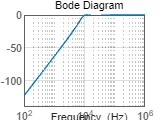

H = simplifyFraction (1.1424/(p^2+0.6265*p+1.1424))*(0.6265/(p+0.6265));
[symNum, symDen] = numden(H);
opts = bodeoptions; opts.Grid = 'on';
opts.PhaseVisible = 'off';
opts.FreqUnits = 'Hz';
bode(sym2poly(symNum),sym2poly(symDen), opts);